# Exámen de robótica

## Introducción

Durante el desarrollo del curso de Robotica, se enseñan las herramientas que permitan comprender a una persona lo que es un robot y como este funciona. Se hace uso de diversas herramientas, que permitan desarrollar un aprendizaje complato en los estudiantes. Parte del proceso de un buen proceso de aprendizaje, requiere poner en práctica los recursos aprendidos durante las lecciones. La robotica, se nutre de ramas como la mecánica y la robótica para describir y poner en marcha a los robots. Los conociminetos de mecánica aplicados en los robots, van desde los conceptos más básicos, hasta los más complejos por analizar. El curso ha partido desde conceptos como cuerpo rígido, la descripción de su posición y ubicación, hasta entrar en el campo de la cinemática y la dinámica. Por ello, se plantea pertinentemente necesaria la aplicación de los conocimientos en el desarrollo de modelos cinemáticos y dinámicos, que permitan identificar el avance o retrazo en la comprensión de los temas. Para el modelado, se hace uso del ejemplo de un robot manipulador SCARA. 

El manipulador **SCARA** (*Selective Compliance Assembly Robot Arm*) fue inventado en 1978 por el profesor Hiroshi Makino de la Universidad de Yamanashi junto con un consorcio industrial. Su diseño destaca por presentar **cumplimiento selectivo**: mantiene una elevada rigidez a lo largo del eje vertical mientras ofrece una alta flexibilidad en el plano horizontal. Típicamente, un robot SCARA consta de **4 ejes de libertad**, donde dos articulaciones de rotación paralelas mueven el brazo en un único plano horizontal y un eje final perpendicular efectúa movimientos de traslación/rotación vertical. Esta topología geométrica predecible y compacta le otorga **alta velocidad, gran precisión de posicionamiento y elevada repetibilidad**, convirtiéndolo en el estándar industrial para tareas de ensamblaje, ordenamiento y operaciones de *pick and place*.

Como ya se menciono anteriormente, el objetivo de este trabajo es identificar los avances que ha adquirido el alumno, además de incitare a estudiar cada uno de los temas abordados dentro del aula. Por ello, se pretende desarrollar el reporte de cada uno de los pasos para el desarrollo de los  cinemático y dinámico.

Dentro del presente codigo se realiza la descripción de un robot SCARA, definiendo inicialmente el modelo cinematico de su posición (modelo directo y modelo inverso). Seguidamente, se desarrolla el modelo directo de las velocidades y el modelo inverso de las velocidades. Se incluye el modelo cinematico de las aceleraciones y el modelo cinematico inverso de las aceleraciones. Un total de 6 modelos cinematicos.

Finalemte se desarrolla el modelo dinámico (directo e inverso) por ecuaciones de Newton-Eüler y Eüler-Lagrange.

## Definición de funciones

Como primer paso, para el desarrollo del modelo cinemático como del dinámico, es útil definir las variables que se emplearan durante todo el codigo. En esta sección, se define la matriz de transformación homogenéa general, dentro de la cual, se alojan la elementos básicos, como las matrices de rotación y los vectores de posición del robot. 

%Deficición de la función de manera simbolica
syms Tij(x_i_j,y_i_j,z_i_j,gi_j,bi_j,ai_j)

%Definición de la transformación homógenea general
Tij(x_i_j,y_i_j,z_i_j,gi_j,bi_j,ai_j) = [cos(ai_j)*cos(bi_j) cos(ai_j)*sin(bi_j)*sin(gi_j)-sin(ai_j)*cos(gi_j) sin(ai_j)*sin(gi_j)+cos(ai_j)*sin(bi_j)*cos(gi_j) x_i_j; sin(ai_j)*cos(bi_j) cos(ai_j)*cos(gi_j)+sin(ai_j)*sin(bi_j)*sin(gi_j) sin(ai_j)*sin(bi_j)*cos(gi_j)-cos(ai_j)*sin(gi_j) y_i_j; -sin(bi_j) cos(bi_j)*sin(gi_j) cos(bi_j)*cos(gi_j) z_i_j; 0 0 0 1]

$$Tij(x\_i\_j, y\_i\_j, z\_i\_j, gi\_j, bi\_j, ai\_j) = \left(\begin{array}{cccc} \cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{bi}}_{j}\right) & \cos\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right)-\cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right) & \sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right)+\cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right) & x_{i,j}\\ \cos\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right) & \cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right)+\sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & \cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)-\cos\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & y_{i,j}\\ -\sin\left({\mathrm{bi}}_{j}\right) & \cos\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & \cos\left({\mathrm{bi}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right) & z_{i,j}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

## Modelado del robot Scara

El modelo de robot en base al cual se hhizo el desarrollo de los modelos, es el robot Scara, compuesto por un total de tres eslabónes, unidos entre si por juntas rotacionales que les permiten hacer movimientos en dos direcciones dentro del plano X Y. La matriz homogenea, constantemente describe la posición y la rotación que el vector adopta según el movimineto que este realiza.

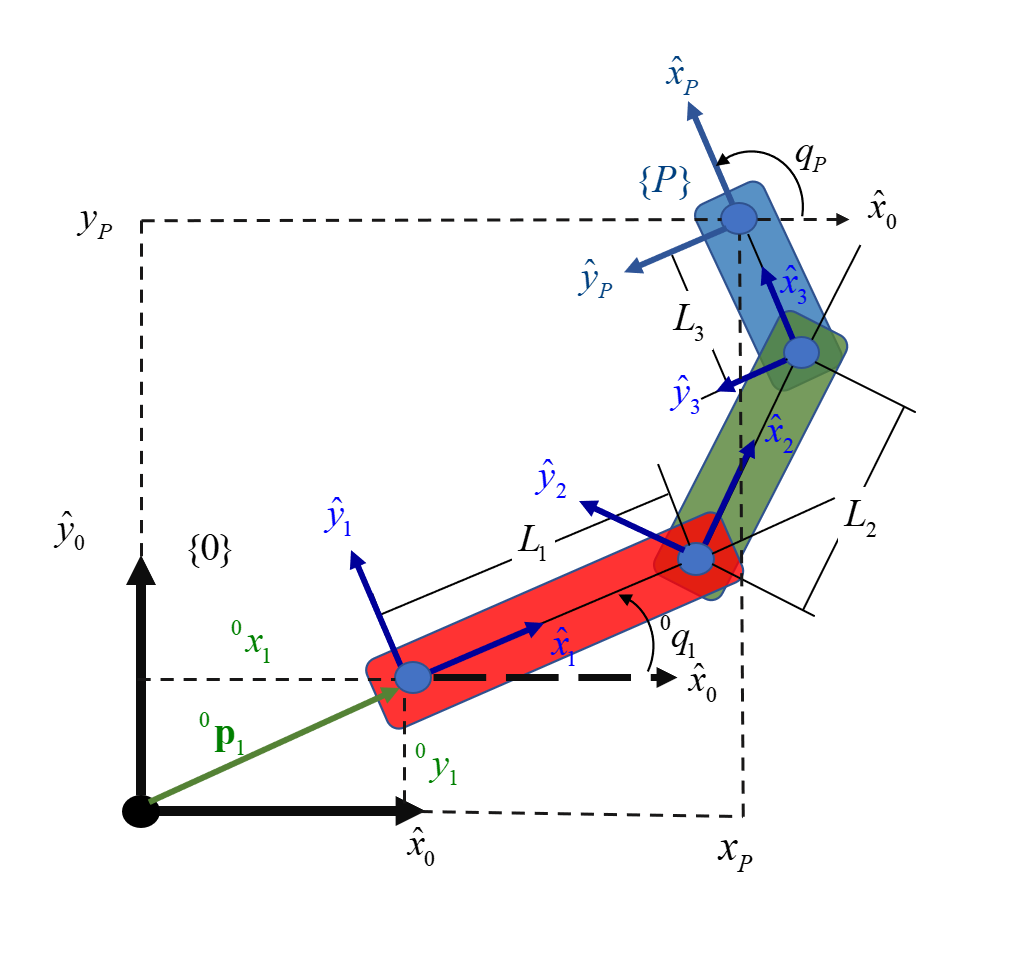

# ***Modelo Cinemático del robot***

El primer modelo a desarrollar ha sido el Modelo Cinemático, esto se explica debido a que, la cinemática establece las bases geométricas del movimiento sobre las cuales se construyen y calculan las ecuaciones dinámicas del robot. En la cinematica se describe la posición, orientación, velocidad y aceleración del robot en el espacio sin considerar las fuerzas o torques producen el movimiento. La dinámica no se puede formular ni resolver sin los resultados cinemáticos previos.

## Modelo cinemático de la postura del robot

### Planteamiento del modelo cinemático de la posición

Este primer planteamiento pretende encontrar el vector pose, que describe a un objeto en el espacio, en este caso el robot scara. Para ello, se "llama" a las matrices de transformación a traves de la matriz homogenéa general. Al ser tres eslabones en total, se requieren las matices que refieran la ubicación de las juntas del eslabón, respecto a los sistemas de referencia que les preceden.

syms x_O_1 y_O_1 theta_O_1 L_2 theta_1_2 L_3 theta_2_3 L_1

T_O_1 = Tij(x_O_1,y_O_1,0,0,0,theta_O_1)

$$T\_O\_1 = \left(\begin{array}{cccc} \cos\left(\theta_{O,1}\right) & -\sin\left(\theta_{O,1}\right) & 0 & x_{O,1}\\ \sin\left(\theta_{O,1}\right) & \cos\left(\theta_{O,1}\right) & 0 & y_{O,1}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_1_2 = Tij(L_1,0,0,0,0,theta_1_2)

$$T\_1\_2 = \left(\begin{array}{cccc} \cos\left(\theta_{1,2}\right) & -\sin\left(\theta_{1,2}\right) & 0 & L_{1}\\ \sin\left(\theta_{1,2}\right) & \cos\left(\theta_{1,2}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_2_3 = Tij(L_2,0,0,0,0,theta_2_3)

$$T\_2\_3 = \left(\begin{array}{cccc} \cos\left(\theta_{2,3}\right) & -\sin\left(\theta_{2,3}\right) & 0 & L_{2}\\ \sin\left(\theta_{2,3}\right) & \cos\left(\theta_{2,3}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_3_P = Tij(L_3,0,0,0,0,0)

$$T\_3\_P = \left(\begin{array}{cccc} 1 & 0 & 0 & L_{3}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


T_O_P = simplify(T_O_1*T_1_2*T_2_3*T_3_P)

$$T\_O\_P = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sigma_{1} & 0 & x_{O,1}+L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)+L_{3}\,\sigma_{2}\\ \sigma_{1} & \sigma_{2} & 0 & y_{O,1}+L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)+L_{3}\,\sigma_{1}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{2}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right) \end{array}$$

### Definición del vector pose

La variable dentro de la cual se guardo la información del vector pose fue:

syms xi_O_P x_O_P y_O_P theta_O_P P_O_P;

xi_O_P

$$xi\_O\_P = \xi_{O,P}$$

#### Vector Pose

Estas son las tres variables dentro de las cuales se describe el punto P (que es el punto más alejado del sistema de referencia {0]) del robot. La pose no es m´sa que la descripción del objeto en el espacio. Estas son las entradas del robot.

xi_O_P =[x_O_P;y_O_P;theta_O_P]

$$xi\_O\_P = \left(\begin{array}{c} x_{O,P}\\ y_{O,P}\\ \theta_{O,P} \end{array}\right)$$

#### Vector de postura del robot

Cuando el robot se mueve, nunca cambiara la longitud de sus eslabones, pero si lo hara su orientación y posición dentro del plano. Por ello, hay que describir variables que permitan ubicarle. Para esto se requiere del vector postura, que toma o captura al objeto en un momento determinado.

xi_O_P_q  = [P_O_P; theta_O_P]

$$xi\_O\_P\_q = \left(\begin{array}{c} P_{O,P}\\ \theta_{O,P} \end{array}\right)$$

Esta es la ecuación descriptiva del robot (Parte Mecánica), en dónde es observable la relación que existe entre cada uno de los eslabónes. El movimiento de uno, depende del estado anterior.

xi_O_P_q = [T_O_P(1,4);T_O_P(2,4);theta_O_1+theta_1_2+theta_2_3]

$$xi\_O\_P\_q = \left(\begin{array}{c} x_{O,1}+L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)+L_{3}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ y_{O,1}+L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)+L_{3}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \theta_{1,2}+\theta_{2,3}+\theta_{O,1} \end{array}\right)$$

Ambos vectores tienen similitudes entre sí, así que la forma de relacionarlos,es mediante la siguiente función: 

%Relación entre vector pose y vector postura


$$F
 =
\left(\begin{array}{c}
x_{O,P} \\
y_{O,P} \\
\theta_{O,P} 
\end{array}\right) 
- 
 \left(\begin{array}{c}
x_{O,1} + L_2\,\cos \left(\theta_{1,2}+\theta_{0,1} \right) + L_1\,\cos \left(\theta_{0,1} \right) + L_3\,\cos \left(\theta_{1,2} + \theta_{2,3} + \theta_{0,1} \right)\\
y_{O,1} + L_2\,\sin\left(\theta_{1,2}+\theta_{0,1} \right) + L_1\,\sin \left(\theta_{0,1} \right) + L_3\,\sin \left(\theta_{1,2} + \theta_{2,3} + \theta_{0,1} \right)\\
\theta_{O,1} + \theta_{2,3} + \theta_{0,1}
\end{array}\right)  = 0$$


F = xi_O_P - xi_O_P_q

$$F = \left(\begin{array}{c} x_{O,P}-x_{O,1}-L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)-L_{1}\,\cos\left(\theta_{O,1}\right)-L_{3}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ y_{O,P}-y_{O,1}-L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)-L_{1}\,\sin\left(\theta_{O,1}\right)-L_{3}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \theta_{O,P}-\theta_{2,3}-\theta_{O,1}-\theta_{1,2} \end{array}\right)$$

%xi_O_P = xi_O_P_q

### Modelo cinemático directo de la postura

Determina la posición y orientación final del efector final del robot en el espacio cartesiano a partir de los ángulos conocidos de sus articulaciones (q)


$$\left(\begin{array}{c}
x_{O,P} \\
y_{O,P} \\
\theta_{O,P} 
\end{array}\right) = \left(\begin{array}{c}
x_{O,1} + L_2\,\cos \left(\theta_{1,2}+\theta_{0,1} \right) + L_1\,\cos \left(\theta_{0,1} \right) + L_3\,\cos \left(\theta_{1,2} + \theta_{2,3} + \theta_{0,1} \right)\\
y_{O,1} + L_2\,\sin\left(\theta_{1,2}+\theta_{0,1} \right) + L_1\,\sin \left(\theta_{0,1} \right) + L_3\,\sin \left(\theta_{1,2} + \theta_{2,3} + \theta_{0,1} \right)\\
\theta_{O,1} + \theta_{2,3} + \theta_{0,1}
\end{array}\right)$$


### Derivada del modelo

#### Modelo Cinemático

Al derivar, se pasa de la posición hacia la velocidad.

syms x_dot_O_P y_dot_O_P theta_dot_O_P theta_dot_O_1 theta_dot_1_2 theta_dot_2_3

xi_dot_O_P = diff(xi_O_P,x_O_P)*x_dot_O_P + diff(xi_O_P,y_O_P)*y_dot_O_P + diff(xi_O_P,theta_O_P)*theta_dot_O_P

$$xi\_dot\_O\_P = \left(\begin{array}{c} {\dot{x}}_{O,P}\\ {\dot{y}}_{O,P}\\ {\dot{\theta }}_{O,P} \end{array}\right)$$

Derivada del vector estado, proyecciones de la velocidad lineal:

xi_dot_O_P_q = diff(xi_O_P_q,theta_O_1)*theta_dot_O_1 +  diff(xi_O_P_q,theta_1_2)*theta_dot_1_2 +  diff(xi_O_P_q,theta_2_3)*theta_dot_2_3

$$xi\_dot\_O\_P\_q = \begin{array}{l} \left(\begin{array}{c} -{\dot{\theta }}_{O,1}\,\left(\sigma_{3}+L_{1}\,\sin\left(\theta_{O,1}\right)+\sigma_{1}\right)-{\dot{\theta }}_{1,2}\,\left(\sigma_{3}+\sigma_{1}\right)-L_{3}\,{\dot{\theta }}_{2,3}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ {\dot{\theta }}_{1,2}\,\left(\sigma_{4}+\sigma_{2}\right)+{\dot{\theta }}_{O,1}\,\left(\sigma_{4}+L_{1}\,\cos\left(\theta_{O,1}\right)+\sigma_{2}\right)+L_{3}\,{\dot{\theta }}_{2,3}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ {\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{3}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{2}=L_{3}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{3}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{4}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right) \end{array}$$

Conjunto (q) de la posición de las juntas:

q = [theta_O_1; theta_1_2; theta_2_3]

$$q = \left(\begin{array}{c} \theta_{O,1}\\ \theta_{1,2}\\ \theta_{2,3} \end{array}\right)$$

Conjunto (q_dot) de las velocidades de juntas:

q_dot = [theta_dot_O_1; theta_dot_1_2; theta_dot_2_3]

$$q\_dot = \left(\begin{array}{c} {\dot{\theta }}_{O,1}\\ {\dot{\theta }}_{1,2}\\ {\dot{\theta }}_{2,3} \end{array}\right)$$

#### Definición del Jacobiano

Al ralizar la derivada del vector xi_O_P_q, se hayan las velocidades, sin embargo, estas no son constantes, son dependientes. No existe una relación directa entre las variables, por ello, es necesario hacer uso de la matriz jacobiana. La función de la Jacobiana, es relacionar la velocidad de movimiento de las articulaciones (q_dot) con la velocidad lineal (v) y la velocidad angular (omega) del efector final en el espacio tridimensional

syms J_theta

J_theta 

$$J\_theta = J_{\theta }$$

J_theta = jacobian(xi_O_P_q, [theta_O_1; theta_1_2; theta_2_3])

$$J\_theta = \begin{array}{l} \left(\begin{array}{ccc} -L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)-L_{1}\,\sin\left(\theta_{O,1}\right)-\sigma_{1} & -L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)-\sigma_{1} & -\sigma_{1}\\ L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)+\sigma_{2} & L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+\sigma_{2} & \sigma_{2}\\ 1 & 1 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{3}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{2}=L_{3}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right) \end{array}$$

## Modelo cinematico directo de las velocidades

La matriz jacobiana Mapea y transforma el valor de las entradas (velocidades), en valores de salida. Traduciendo las acciones al espacio cartesiano

xi_dot_O_P = J_theta * q_dot

$$xi\_dot\_O\_P = \begin{array}{l} \left(\begin{array}{c} -{\dot{\theta }}_{O,1}\,\left(\sigma_{3}+L_{1}\,\sin\left(\theta_{O,1}\right)+\sigma_{1}\right)-{\dot{\theta }}_{1,2}\,\left(\sigma_{3}+\sigma_{1}\right)-L_{3}\,{\dot{\theta }}_{2,3}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ {\dot{\theta }}_{1,2}\,\left(\sigma_{4}+\sigma_{2}\right)+{\dot{\theta }}_{O,1}\,\left(\sigma_{4}+L_{1}\,\cos\left(\theta_{O,1}\right)+\sigma_{2}\right)+L_{3}\,{\dot{\theta }}_{2,3}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ {\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{3}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{2}=L_{3}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{3}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{4}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right) \end{array}$$

## Modelo cinemático inverso de las velocidades

inv(J_theta)

$$ans = \begin{array}{l} \left(\begin{array}{ccc} -\frac{\cos\left(\theta_{1,2}+\theta_{O,1}\right)}{\sigma_{2}} & -\frac{\sin\left(\theta_{1,2}+\theta_{O,1}\right)}{\sigma_{2}} & \frac{L_{3}\,\sigma_{4}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)-L_{3}\,\sigma_{3}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)}{\sigma_{2}}\\ \frac{L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)}{\sigma_{1}} & \frac{L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)}{\sigma_{1}} & -\frac{L_{1}\,L_{3}\,\sigma_{4}\,\sin\left(\theta_{O,1}\right)-L_{1}\,L_{3}\,\sigma_{3}\,\cos\left(\theta_{O,1}\right)+L_{2}\,L_{3}\,\sigma_{4}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)-L_{2}\,L_{3}\,\sigma_{3}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)}{\sigma_{1}}\\ -\frac{\cos\left(\theta_{O,1}\right)}{\sigma_{6}-\sigma_{5}} & -\frac{\sin\left(\theta_{O,1}\right)}{\sigma_{6}-\sigma_{5}} & \frac{\sigma_{6}-\sigma_{5}+L_{3}\,\sigma_{4}\,\sin\left(\theta_{O,1}\right)-L_{3}\,\sigma_{3}\,\cos\left(\theta_{O,1}\right)}{\sigma_{6}-\sigma_{5}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{1}\,L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\,\sin\left(\theta_{O,1}\right)-L_{1}\,L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\,\cos\left(\theta_{O,1}\right)\\ \sigma_{2}=L_{1}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\,\sin\left(\theta_{O,1}\right)-L_{1}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\,\cos\left(\theta_{O,1}\right)\\ \sigma_{3}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{4}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{5}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\,\cos\left(\theta_{O,1}\right)\\ \sigma_{6}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\,\sin\left(\theta_{O,1}\right) \end{array}$$

El modelo inverso, permite realizar movimientos más complejos, como la aparición de obstaculos en el espacio de trabajo, que requieran la planeación de nuevas rutas para llegar a un determinado punto final.


q_dot = inv(J_theta) * xi_dot_O_P

## Modelo cinemático de las aceleaciones

### Cálculo de las aceleraciones del eslabón

syms x_dot_O_P y_dot_O_P theta_dot_O_P x_ddot_O_P y_ddot_O_P theta_ddot_O_P theta_ddot_O_1 theta_ddot_1_2 theta_ddot_2_3

%vector de velocidad
xi_dot_O_P = [x_dot_O_P; y_dot_O_P;theta_dot_O_P]

$$xi\_dot\_O\_P = \left(\begin{array}{c} {\dot{x}}_{O,P}\\ {\dot{y}}_{O,P}\\ {\dot{\theta }}_{O,P} \end{array}\right)$$


%vector de aceleracion
xi_ddot_O_P = [x_ddot_O_P; y_ddot_O_P;theta_ddot_O_P]

$$xi\_ddot\_O\_P = \left(\begin{array}{c} {\ddot{x}}_{O,P}\\ {\ddot{y}}_{O,P}\\ {\ddot{\theta }}_{O,P} \end{array}\right)$$

q_ddot = [theta_ddot_O_1; theta_ddot_1_2; theta_ddot_2_3]

$$q\_ddot = \left(\begin{array}{c} {\ddot{\theta }}_{O,1}\\ {\ddot{\theta }}_{1,2}\\ {\ddot{\theta }}_{2,3} \end{array}\right)$$

%calulo de las velocidades


%xi_ddot_O_P_q = diff(xi_dot_O_P_q, theta_O_1)*theta_dot_O_1 + diff(xi_dot_O_P_q, theta_dot_O_1)*theta_ddot_O_1
J_dot_theta = diff(J_theta, theta_O_1) * theta_dot_O_1 + diff(J_theta, theta_1_2)*theta_dot_1_2 + diff(J_theta, theta_2_3)*theta_dot_2_3

$$J\_dot\_theta = \begin{array}{l} \left(\begin{array}{ccc} -\sigma_{1}-{\dot{\theta }}_{O,1}\,\left(\sigma_{4}+L_{1}\,\cos\left(\theta_{O,1}\right)+L_{3}\,\sigma_{3}\right)-L_{3}\,{\dot{\theta }}_{2,3}\,\sigma_{3} & -\sigma_{1}-{\dot{\theta }}_{O,1}\,\left(\sigma_{4}+L_{3}\,\sigma_{3}\right)-L_{3}\,{\dot{\theta }}_{2,3}\,\sigma_{3} & -L_{3}\,{\dot{\theta }}_{1,2}\,\sigma_{3}-L_{3}\,{\dot{\theta }}_{2,3}\,\sigma_{3}-L_{3}\,{\dot{\theta }}_{O,1}\,\sigma_{3}\\ -{\dot{\theta }}_{O,1}\,\left(\sigma_{6}+L_{1}\,\sin\left(\theta_{O,1}\right)+L_{3}\,\sigma_{5}\right)-\sigma_{2}-L_{3}\,{\dot{\theta }}_{2,3}\,\sigma_{5} & -\sigma_{2}-{\dot{\theta }}_{O,1}\,\left(\sigma_{6}+L_{3}\,\sigma_{5}\right)-L_{3}\,{\dot{\theta }}_{2,3}\,\sigma_{5} & -L_{3}\,{\dot{\theta }}_{1,2}\,\sigma_{5}-L_{3}\,{\dot{\theta }}_{2,3}\,\sigma_{5}-L_{3}\,{\dot{\theta }}_{O,1}\,\sigma_{5}\\ 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\dot{\theta }}_{1,2}\,\left(\sigma_{4}+L_{3}\,\sigma_{3}\right)\\ \sigma_{2}={\dot{\theta }}_{1,2}\,\left(\sigma_{6}+L_{3}\,\sigma_{5}\right)\\ \sigma_{3}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{4}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{5}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{6}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right) \end{array}$$

## Modelo cinematico directo de las aceleraciones

Aqui se describen las articulaciones, relacionando sus aceleraciones y sus velociades. En la segunda parte de la suma, se encuentra la aceleración virtual, que es la proyección hacia el punto de vita del observador. La analogía planteada en el curso para esta función, es la comparación con la cmpuerta logica AND. Esto significa, que para obtener un resultado, ambos miembros han de expresar valores positivos.

xi_ddot_O_P = (J_theta * q_ddot ) + (J_dot_theta*q_dot)

## Modelo cinematico inverso de las aceleraciones

%inv(J_dot_theta)
J_dot_theta_inv =  diff(J_dot_theta, theta_O_1) * theta_dot_O_1 + diff(J_dot_theta, theta_1_2)*theta_dot_1_2 + diff(J_dot_theta, theta_2_3)*theta_dot_2_3

q_ddot = (inv(J_theta) * xi_ddot_O_P) + (J_dot_theta_inv * xi_dot_O_P)

## Modelo Dinámico por ecuaciones de Eüler-Lagrange

### Por ecuciones de Newton-Eüler

#### Condiciones iniciales

Igualadas a 0 porque el par contrarresta todos los momentos

%Velocidad angular w en el sistema {O}

omega_O_O = [0;0;0]

omega_O_O =      0
     0
     0


%Aceleración angular en el sistema {O}

omega_dot_O_O = [0;0;0]

omega_dot_O_O =      0
     0
     0


%Aceleración lineal en el sistema {O}

v_dot_O_O = [0;-g;0]

$$v\_dot\_O\_O = \left(\begin{array}{c} 0\\ -g\\ 0 \end{array}\right)$$

### Iteraciones exteriores

#### Velocidades angulares 

%Propagación para el primer cuerpo
omega_1_1

$$omega\_1\_1 = \left(\begin{array}{c} 0\\ 0\\ {\dot{\theta }}_{O,1} \end{array}\right)$$

%Eje donde se aplica el giro
n_1_1 = [0;0;1]

n_1_1 =      0
     0
     1


%Matriz de rotación de {O} a {1}
R_O_1 = [T_O_1(1,1),T_O_1(1,2),T_O_1(1,3);T_O_1(2,1),T_O_1(2,2),T_O_1(2,3);T_O_1(3,1),T_O_1(3,2),T_O_1(3,3)]

$$R\_O\_1 = \left(\begin{array}{ccc} \cos\left(\theta_{O,1}\right) & -\sin\left(\theta_{O,1}\right) & 0\\ \sin\left(\theta_{O,1}\right) & \cos\left(\theta_{O,1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

%Matriz Transpuesta
R_1_O = transpose(R_O_1)

$$R\_1\_O = \left(\begin{array}{ccc} \cos\left(\theta_{O,1}\right) & \sin\left(\theta_{O,1}\right) & 0\\ -\sin\left(\theta_{O,1}\right) & \cos\left(\theta_{O,1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$


%Ecuación de propagación (primer cuerpo) Velocidad angular
omega_1_1 = (R_1_O*omega_O_O) + (n_1_1*theta_dot_O_1)

$$omega\_1\_1 = \left(\begin{array}{c} 0\\ 0\\ {\dot{\theta }}_{O,1} \end{array}\right)$$

%Propagación para el segundo cuerpo
omega_2_2

$$omega\_2\_2 = \left(\begin{array}{c} 0\\ 0\\ {\dot{\theta }}_{1,2}+{\dot{\theta }}_{O,1} \end{array}\right)$$

%Eje donde se aplica el giro
n_2_2 = [0;0;1]

n_2_2 =      0
     0
     1


R_1_2 = [T_1_2(1,1),T_1_2(1,2),T_1_2(1,3);T_1_2(2,1),T_1_2(2,2),T_1_2(2,3);T_1_2(3,1),T_1_2(3,2),T_1_2(3,3)]

$$R\_1\_2 = \left(\begin{array}{ccc} \cos\left(\theta_{1,2}\right) & -\sin\left(\theta_{1,2}\right) & 0\\ \sin\left(\theta_{1,2}\right) & \cos\left(\theta_{1,2}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R_2_1 = transpose(R_1_2)

$$R\_2\_1 = \left(\begin{array}{ccc} \cos\left(\theta_{1,2}\right) & \sin\left(\theta_{1,2}\right) & 0\\ -\sin\left(\theta_{1,2}\right) & \cos\left(\theta_{1,2}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$


%Ecuación de propagación (segundo cuerpo)
omega_2_2 = R_2_1*omega_1_1+n_2_2*theta_dot_1_2

$$omega\_2\_2 = \left(\begin{array}{c} 0\\ 0\\ {\dot{\theta }}_{1,2}+{\dot{\theta }}_{O,1} \end{array}\right)$$

%Propagación para el tercer cuerpo
omega_3_3

$$omega\_3\_3 = \left(\begin{array}{c} 0\\ 0\\ {\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1} \end{array}\right)$$

%Eje donde se aplica el giro
n_3_3 = [0;0;1]

n_3_3 =      0
     0
     1


%Matriz de rotación de {1} a {2}
R_2_3 = [T_2_3(1,1),T_2_3(1,2),T_2_3(1,3);T_2_3(2,1),T_2_3(2,2),T_2_3(2,3);T_2_3(3,1),T_2_3(3,2),T_2_3(3,3)]

$$R\_2\_3 = \left(\begin{array}{ccc} \cos\left(\theta_{2,3}\right) & -\sin\left(\theta_{2,3}\right) & 0\\ \sin\left(\theta_{2,3}\right) & \cos\left(\theta_{2,3}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

%Matriz Transpuesta
R_3_2 = transpose(R_2_3)

$$R\_3\_2 = \left(\begin{array}{ccc} \cos\left(\theta_{2,3}\right) & \sin\left(\theta_{2,3}\right) & 0\\ -\sin\left(\theta_{2,3}\right) & \cos\left(\theta_{2,3}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$


%Ecuación de propagación (Tercer cuerpo)
omega_3_3 = R_3_2*omega_2_2+n_3_3*theta_dot_2_3

$$omega\_3\_3 = \left(\begin{array}{c} 0\\ 0\\ {\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1} \end{array}\right)$$

#### Aceleración angular

omega_1_1 

$$omega\_1\_1 = \left(\begin{array}{c} 0\\ 0\\ {\dot{\theta }}_{O,1} \end{array}\right)$$

omega_2_2

$$omega\_2\_2 = \left(\begin{array}{c} 0\\ 0\\ {\dot{\theta }}_{1,2}+{\dot{\theta }}_{O,1} \end{array}\right)$$

omega_3_3

$$omega\_3\_3 = \left(\begin{array}{c} 0\\ 0\\ {\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1} \end{array}\right)$$


omega_dot_1_1 = (R_1_O*omega_dot_O_O) + cross((R_1_O*omega_O_O),(theta_dot_O_1*n_1_1)) + theta_ddot_O_1*n_1_1

$$omega\_dot\_1\_1 = \left(\begin{array}{c} 0\\ 0\\ {\ddot{\theta }}_{O,1} \end{array}\right)$$

omega_dot_2_2 = (R_2_1*omega_dot_1_1) + cross((R_2_1*omega_1_1),(theta_dot_1_2*n_2_2)) + theta_ddot_1_2*n_2_2

$$omega\_dot\_2\_2 = \left(\begin{array}{c} 0\\ 0\\ {\ddot{\theta }}_{1,2}+{\ddot{\theta }}_{O,1} \end{array}\right)$$

omega_dot_3_3 = (R_3_2*omega_dot_2_2) + cross((R_3_2*omega_2_2),(theta_dot_2_3*n_3_3)) + theta_ddot_2_3*n_3_3

$$omega\_dot\_3\_3 = \left(\begin{array}{c} 0\\ 0\\ {\ddot{\theta }}_{1,2}+{\ddot{\theta }}_{2,3}+{\ddot{\theta }}_{O,1} \end{array}\right)$$

#### Aceleración lineal del origen del sistema de referencia

syms x_O_1 x_1_2 x_2_3
%Posición de la junta respecto al sistema de origen
T_O_1

$$T\_O\_1 = \left(\begin{array}{cccc} \cos\left(\theta_{O,1}\right) & -\sin\left(\theta_{O,1}\right) & 0 & x_{O,1}\\ \sin\left(\theta_{O,1}\right) & \cos\left(\theta_{O,1}\right) & 0 & y_{O,1}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_O_1 = Tij(x_O_1,0,0,0,0,0)

$$T\_O\_1 = \left(\begin{array}{cccc} 1 & 0 & 0 & x_{O,1}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

P_O_1 = [T_O_1(1,4);T_O_1(2,4);T_O_1(3,4)]

$$P\_O\_1 = \left(\begin{array}{c} x_{O,1}\\ 0\\ 0 \end{array}\right)$$

v_dot_1_1 = R_1_O * (cross(omega_dot_O_O, P_O_1) + cross(omega_O_O, (cross(omega_O_O, P_O_1))) + v_dot_O_O)

$$v\_dot\_1\_1 = \left(\begin{array}{c} -g\,\sin\left(\theta_{O,1}\right)\\ -g\,\cos\left(\theta_{O,1}\right)\\ 0 \end{array}\right)$$

T_1_2

$$T\_1\_2 = \left(\begin{array}{cccc} \cos\left(\theta_{1,2}\right) & -\sin\left(\theta_{1,2}\right) & 0 & L_{1}\\ \sin\left(\theta_{1,2}\right) & \cos\left(\theta_{1,2}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_1_2 = Tij(x_1_2,0,0,0,0,0)

$$T\_1\_2 = \left(\begin{array}{cccc} 1 & 0 & 0 & x_{1,2}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

P_1_2 = simplify([T_1_2(1,4);T_1_2(2,4);T_1_2(3,4)])

$$P\_1\_2 = \left(\begin{array}{c} x_{1,2}\\ 0\\ 0 \end{array}\right)$$


v_dot_2_2 = R_2_1 * (cross(omega_dot_1_1, P_1_2) + cross(omega_1_1, (cross(omega_1_1, P_1_2))) + v_dot_1_1)

$$v\_dot\_2\_2 = \left(\begin{array}{c} \sin\left(\theta_{1,2}\right)\,\left({\ddot{\theta }}_{O,1}\,x_{1,2}-g\,\cos\left(\theta_{O,1}\right)\right)-\cos\left(\theta_{1,2}\right)\,\left(x_{1,2}\,{{\dot{\theta }}_{O,1}}^{2}+g\,\sin\left(\theta_{O,1}\right)\right)\\ \sin\left(\theta_{1,2}\right)\,\left(x_{1,2}\,{{\dot{\theta }}_{O,1}}^{2}+g\,\sin\left(\theta_{O,1}\right)\right)+\cos\left(\theta_{1,2}\right)\,\left({\ddot{\theta }}_{O,1}\,x_{1,2}-g\,\cos\left(\theta_{O,1}\right)\right)\\ 0 \end{array}\right)$$




T_2_3

$$T\_2\_3 = \left(\begin{array}{cccc} \cos\left(\theta_{2,3}\right) & -\sin\left(\theta_{2,3}\right) & 0 & L_{2}\\ \sin\left(\theta_{2,3}\right) & \cos\left(\theta_{2,3}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_2_3 = Tij(x_2_3,0,0,0,0,0)

$$T\_2\_3 = \left(\begin{array}{cccc} 1 & 0 & 0 & x_{2,3}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

P_2_3 = simplify([T_2_3(1,4);T_2_3(2,4);T_2_3(3,4)])

$$P\_2\_3 = \left(\begin{array}{c} x_{2,3}\\ 0\\ 0 \end{array}\right)$$


v_dot_3_3 = R_3_2 * (cross(omega_dot_2_2, P_2_3) + cross(omega_2_2, (cross(omega_2_2, P_2_3))) + v_dot_2_2)

$$v\_dot\_3\_3 = \begin{array}{l} \left(\begin{array}{c} \sin\left(\theta_{2,3}\right)\,\sigma_{2}-\cos\left(\theta_{2,3}\right)\,\sigma_{1}\\ \cos\left(\theta_{2,3}\right)\,\sigma_{2}+\sin\left(\theta_{2,3}\right)\,\sigma_{1}\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=x_{2,3}\,{\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{O,1}\right)}^{2}-\sin\left(\theta_{1,2}\right)\,\left({\ddot{\theta }}_{O,1}\,x_{1,2}-g\,\cos\left(\theta_{O,1}\right)\right)+\cos\left(\theta_{1,2}\right)\,\left(x_{1,2}\,{{\dot{\theta }}_{O,1}}^{2}+g\,\sin\left(\theta_{O,1}\right)\right)\\ \sigma_{2}=\sin\left(\theta_{1,2}\right)\,\left(x_{1,2}\,{{\dot{\theta }}_{O,1}}^{2}+g\,\sin\left(\theta_{O,1}\right)\right)+x_{2,3}\,\left({\ddot{\theta }}_{1,2}+{\ddot{\theta }}_{O,1}\right)+\cos\left(\theta_{1,2}\right)\,\left({\ddot{\theta }}_{O,1}\,x_{1,2}-g\,\cos\left(\theta_{O,1}\right)\right) \end{array}$$

#### Aceleración lineal del centro de masa

syms x_1_C1 x_2_C2 x_3_C3

%Posición de los centros de masa desde el sistema {O}, {1}, {2} y {3} respectivamente
T_1_C1 = Tij(x_1_C1,0,0,0,0,0)

$$T\_1\_C1 = \left(\begin{array}{cccc} 1 & 0 & 0 & x_{1,\mathrm{C1}}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$



T_2_C2 = Tij(x_2_C2,0,0,0,0,0)

$$T\_2\_C2 = \left(\begin{array}{cccc} 1 & 0 & 0 & x_{2,\mathrm{C2}}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$



T_3_C3 = Tij(x_3_C3,0,0,0,0,0)

$$T\_3\_C3 = \left(\begin{array}{cccc} 1 & 0 & 0 & x_{3,\mathrm{C3}}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$




%Vectores de posición de los centros de masa, respecto al sistema {O}
P_1_C1 = [T_O_C1(1,4);T_O_C1(2,4);T_O_C1(3,4)]

$$P\_1\_C1 = \left(\begin{array}{c} x_{1,\mathrm{C1}}+x_{O,1}\\ 0\\ 0 \end{array}\right)$$

P_2_C2 = simplify([T_O_C2(1,4);T_O_C2(2,4);T_O_C2(3,4)])

$$P\_2\_C2 = \left(\begin{array}{c} x_{1,2}+x_{2,\mathrm{C2}}+x_{O,1}\\ 0\\ 0 \end{array}\right)$$


P_3_C3 = simplify([T_O_C3(1,4);T_O_C3(2,4);T_O_C3(3,4)])

$$P\_3\_C3 = \left(\begin{array}{c} x_{1,2}+x_{2,3}+x_{3,\mathrm{C3}}+x_{O,1}\\ 0\\ 0 \end{array}\right)$$


syms theta_dot_O_1 theta_dot_1_2 theta_dot_2_3

v_dot_1_C1 = cross(omega_dot_1_1, P_1_C1) + cross(omega_1_1, cross(omega_1_1, P_1_C1) + v_dot_1_1)

$$v\_dot\_1\_C1 = \left(\begin{array}{c} -{\dot{\theta }}_{O,1}\,\left({\dot{\theta }}_{O,1}\,\left(x_{1,\mathrm{C1}}+x_{O,1}\right)-g\,\cos\left(\theta_{O,1}\right)\right)\\ {\ddot{\theta }}_{O,1}\,\left(x_{1,\mathrm{C1}}+x_{O,1}\right)-g\,{\dot{\theta }}_{O,1}\,\sin\left(\theta_{O,1}\right)\\ 0 \end{array}\right)$$

v_dot_2_C2 = cross(omega_dot_2_2, P_2_C2) + cross(omega_2_2, cross(omega_2_2, P_2_C2) + v_dot_2_2)

$$v\_dot\_2\_C2 = \begin{array}{l} \left(\begin{array}{c} -\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{O,1}\right)\,\left(\sin\left(\theta_{1,2}\right)\,\sigma_{1}+\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{O,1}\right)\,\left(x_{1,2}+x_{2,\mathrm{C2}}+x_{O,1}\right)+\cos\left(\theta_{1,2}\right)\,\left({\ddot{\theta }}_{O,1}\,x_{1,2}-g\,\cos\left(\theta_{O,1}\right)\right)\right)\\ \left({\ddot{\theta }}_{1,2}+{\ddot{\theta }}_{O,1}\right)\,\left(x_{1,2}+x_{2,\mathrm{C2}}+x_{O,1}\right)+\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{O,1}\right)\,\left(\sin\left(\theta_{1,2}\right)\,\left({\ddot{\theta }}_{O,1}\,x_{1,2}-g\,\cos\left(\theta_{O,1}\right)\right)-\cos\left(\theta_{1,2}\right)\,\sigma_{1}\right)\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=x_{1,2}\,{{\dot{\theta }}_{O,1}}^{2}+g\,\sin\left(\theta_{O,1}\right) \end{array}$$

v_dot_3_C3 = cross(omega_dot_3_3, P_3_C3) + cross(omega_3_3, cross(omega_3_3, P_3_C3) + v_dot_3_3)

$$v\_dot\_3\_C3 = \begin{array}{l} \left(\begin{array}{c} -\left(\cos\left(\theta_{2,3}\right)\,\sigma_{2}+\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1}\right)\,\left(x_{1,2}+x_{2,3}+x_{3,\mathrm{C3}}+x_{O,1}\right)+\sin\left(\theta_{2,3}\right)\,\sigma_{1}\right)\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1}\right)\\ \left(\sin\left(\theta_{2,3}\right)\,\sigma_{2}-\cos\left(\theta_{2,3}\right)\,\sigma_{1}\right)\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1}\right)+\left({\ddot{\theta }}_{1,2}+{\ddot{\theta }}_{2,3}+{\ddot{\theta }}_{O,1}\right)\,\left(x_{1,2}+x_{2,3}+x_{3,\mathrm{C3}}+x_{O,1}\right)\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=x_{2,3}\,{\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{O,1}\right)}^{2}-\sin\left(\theta_{1,2}\right)\,\left({\ddot{\theta }}_{O,1}\,x_{1,2}-g\,\cos\left(\theta_{O,1}\right)\right)+\cos\left(\theta_{1,2}\right)\,\left(x_{1,2}\,{{\dot{\theta }}_{O,1}}^{2}+g\,\sin\left(\theta_{O,1}\right)\right)\\ \sigma_{2}=\sin\left(\theta_{1,2}\right)\,\left(x_{1,2}\,{{\dot{\theta }}_{O,1}}^{2}+g\,\sin\left(\theta_{O,1}\right)\right)+x_{2,3}\,\left({\ddot{\theta }}_{1,2}+{\ddot{\theta }}_{O,1}\right)+\cos\left(\theta_{1,2}\right)\,\left({\ddot{\theta }}_{O,1}\,x_{1,2}-g\,\cos\left(\theta_{O,1}\right)\right) \end{array}$$

#### Ecuación de Newton

Fuerza neta de los vinculos

F_1_1 = m_1 * v_dot_1_C1

$$F\_1\_1 = \left(\begin{array}{c} -m_{1}\,{\dot{\theta }}_{O,1}\,\left({\dot{\theta }}_{O,1}\,\left(x_{1,\mathrm{C1}}+x_{O,1}\right)-g\,\cos\left(\theta_{O,1}\right)\right)\\ m_{1}\,\left({\ddot{\theta }}_{O,1}\,\left(x_{1,\mathrm{C1}}+x_{O,1}\right)-g\,{\dot{\theta }}_{O,1}\,\sin\left(\theta_{O,1}\right)\right)\\ 0 \end{array}\right)$$

F_2_2 = m_2 * v_dot_2_C2

$$F\_2\_2 = \begin{array}{l} \left(\begin{array}{c} -m_{2}\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{O,1}\right)\,\left(\sin\left(\theta_{1,2}\right)\,\sigma_{1}+\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{O,1}\right)\,\left(x_{1,2}+x_{2,\mathrm{C2}}+x_{O,1}\right)+\cos\left(\theta_{1,2}\right)\,\left({\ddot{\theta }}_{O,1}\,x_{1,2}-g\,\cos\left(\theta_{O,1}\right)\right)\right)\\ m_{2}\,\left(\left({\ddot{\theta }}_{1,2}+{\ddot{\theta }}_{O,1}\right)\,\left(x_{1,2}+x_{2,\mathrm{C2}}+x_{O,1}\right)+\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{O,1}\right)\,\left(\sin\left(\theta_{1,2}\right)\,\left({\ddot{\theta }}_{O,1}\,x_{1,2}-g\,\cos\left(\theta_{O,1}\right)\right)-\cos\left(\theta_{1,2}\right)\,\sigma_{1}\right)\right)\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=x_{1,2}\,{{\dot{\theta }}_{O,1}}^{2}+g\,\sin\left(\theta_{O,1}\right) \end{array}$$

F_3_3 = m_3 * v_dot_3_C3

$$F\_3\_3 = \begin{array}{l} \left(\begin{array}{c} -m_{3}\,\left(\cos\left(\theta_{2,3}\right)\,\sigma_{2}+\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1}\right)\,\left(x_{1,2}+x_{2,3}+x_{3,\mathrm{C3}}+x_{O,1}\right)+\sin\left(\theta_{2,3}\right)\,\sigma_{1}\right)\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1}\right)\\ m_{3}\,\left(\left(\sin\left(\theta_{2,3}\right)\,\sigma_{2}-\cos\left(\theta_{2,3}\right)\,\sigma_{1}\right)\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1}\right)+\left({\ddot{\theta }}_{1,2}+{\ddot{\theta }}_{2,3}+{\ddot{\theta }}_{O,1}\right)\,\left(x_{1,2}+x_{2,3}+x_{3,\mathrm{C3}}+x_{O,1}\right)\right)\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=x_{2,3}\,{\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{O,1}\right)}^{2}-\sin\left(\theta_{1,2}\right)\,\left({\ddot{\theta }}_{O,1}\,x_{1,2}-g\,\cos\left(\theta_{O,1}\right)\right)+\cos\left(\theta_{1,2}\right)\,\left(x_{1,2}\,{{\dot{\theta }}_{O,1}}^{2}+g\,\sin\left(\theta_{O,1}\right)\right)\\ \sigma_{2}=\sin\left(\theta_{1,2}\right)\,\left(x_{1,2}\,{{\dot{\theta }}_{O,1}}^{2}+g\,\sin\left(\theta_{O,1}\right)\right)+x_{2,3}\,\left({\ddot{\theta }}_{1,2}+{\ddot{\theta }}_{O,1}\right)+\cos\left(\theta_{1,2}\right)\,\left({\ddot{\theta }}_{O,1}\,x_{1,2}-g\,\cos\left(\theta_{O,1}\right)\right) \end{array}$$

#### Ecuación de Euler

syms g I_xx1 I_yy1 I_zz1 I_xx2 I_yy2 I_zz2 I_xx3 I_yy3 I_zz3

I_C1 = [I_xx1,0,0;0,I_yy1,0;0,0,I_zz1]

$$I\_C1 = \left(\begin{array}{ccc} I_{\mathrm{xx1}} & 0 & 0\\ 0 & I_{\mathrm{yy1}} & 0\\ 0 & 0 & I_{\mathrm{zz1}} \end{array}\right)$$

I_C2 = [I_xx2,0,0;0,I_yy2,0;0,0,I_zz2]

$$I\_C2 = \left(\begin{array}{ccc} I_{\mathrm{xx2}} & 0 & 0\\ 0 & I_{\mathrm{yy2}} & 0\\ 0 & 0 & I_{\mathrm{zz2}} \end{array}\right)$$

I_C3 = [I_xx3,0,0;0,I_yy3,0;0,0,I_zz3]

$$I\_C3 = \left(\begin{array}{ccc} I_{\mathrm{xx3}} & 0 & 0\\ 0 & I_{\mathrm{yy3}} & 0\\ 0 & 0 & I_{\mathrm{zz3}} \end{array}\right)$$



I_1_C1 = m_1*(transpose(P_1_C1)*P_1_C1*[1,0,0;0,1,0;0,0,1]+P_1_C1*transpose(P_1_C1)) + I_C1

$$I\_1\_C1 = \left(\begin{array}{ccc} I_{\mathrm{xx1}}+2\,m_{1}\,{\left(x_{1,\mathrm{C1}}+x_{O,1}\right)}^{2} & 0 & 0\\ 0 & I_{\mathrm{yy1}}+m_{1}\,{\left(x_{1,\mathrm{C1}}+x_{O,1}\right)}^{2} & 0\\ 0 & 0 & I_{\mathrm{zz1}}+m_{1}\,{\left(x_{1,\mathrm{C1}}+x_{O,1}\right)}^{2} \end{array}\right)$$

I_2_C2 = m_2*(transpose(P_2_C2)*P_2_C2*[1,0,0;0,1,0;0,0,1]+P_2_C2*transpose(P_2_C2)) + I_C2

$$I\_2\_C2 = \left(\begin{array}{ccc} I_{\mathrm{xx2}}+2\,m_{2}\,{\left(x_{1,2}+x_{2,\mathrm{C2}}+x_{O,1}\right)}^{2} & 0 & 0\\ 0 & I_{\mathrm{yy2}}+m_{2}\,{\left(x_{1,2}+x_{2,\mathrm{C2}}+x_{O,1}\right)}^{2} & 0\\ 0 & 0 & I_{\mathrm{zz2}}+m_{2}\,{\left(x_{1,2}+x_{2,\mathrm{C2}}+x_{O,1}\right)}^{2} \end{array}\right)$$

I_3_C3 = m_3*(transpose(P_3_C3)*P_3_C3*[1,0,0;0,1,0;0,0,1]+P_3_C3*transpose(P_3_C3)) + I_C3

$$I\_3\_C3 = \left(\begin{array}{ccc} I_{\mathrm{xx3}}+2\,m_{3}\,{\left(x_{1,2}+x_{2,3}+x_{3,\mathrm{C3}}+x_{O,1}\right)}^{2} & 0 & 0\\ 0 & I_{\mathrm{yy3}}+m_{3}\,{\left(x_{1,2}+x_{2,3}+x_{3,\mathrm{C3}}+x_{O,1}\right)}^{2} & 0\\ 0 & 0 & I_{\mathrm{zz3}}+m_{3}\,{\left(x_{1,2}+x_{2,3}+x_{3,\mathrm{C3}}+x_{O,1}\right)}^{2} \end{array}\right)$$



I_C1_1 = transpose(I_1_C1)

$$I\_C1\_1 = \left(\begin{array}{ccc} I_{\mathrm{xx1}}+2\,m_{1}\,{\left(x_{1,\mathrm{C1}}+x_{O,1}\right)}^{2} & 0 & 0\\ 0 & I_{\mathrm{yy1}}+m_{1}\,{\left(x_{1,\mathrm{C1}}+x_{O,1}\right)}^{2} & 0\\ 0 & 0 & I_{\mathrm{zz1}}+m_{1}\,{\left(x_{1,\mathrm{C1}}+x_{O,1}\right)}^{2} \end{array}\right)$$

I_C2_2 = transpose(I_2_C2)

$$I\_C2\_2 = \left(\begin{array}{ccc} I_{\mathrm{xx2}}+2\,m_{2}\,{\left(x_{1,2}+x_{2,\mathrm{C2}}+x_{O,1}\right)}^{2} & 0 & 0\\ 0 & I_{\mathrm{yy2}}+m_{2}\,{\left(x_{1,2}+x_{2,\mathrm{C2}}+x_{O,1}\right)}^{2} & 0\\ 0 & 0 & I_{\mathrm{zz2}}+m_{2}\,{\left(x_{1,2}+x_{2,\mathrm{C2}}+x_{O,1}\right)}^{2} \end{array}\right)$$

I_C3_3 = transpose(I_3_C3)

$$I\_C3\_3 = \left(\begin{array}{ccc} I_{\mathrm{xx3}}+2\,m_{3}\,{\left(x_{1,2}+x_{2,3}+x_{3,\mathrm{C3}}+x_{O,1}\right)}^{2} & 0 & 0\\ 0 & I_{\mathrm{yy3}}+m_{3}\,{\left(x_{1,2}+x_{2,3}+x_{3,\mathrm{C3}}+x_{O,1}\right)}^{2} & 0\\ 0 & 0 & I_{\mathrm{zz3}}+m_{3}\,{\left(x_{1,2}+x_{2,3}+x_{3,\mathrm{C3}}+x_{O,1}\right)}^{2} \end{array}\right)$$



N_1_1 = I_C1_1 * omega_dot_1_1 + cross(omega_1_1, (I_C1_1 * omega_1_1))

$$N\_1\_1 = \left(\begin{array}{c} 0\\ 0\\ {\ddot{\theta }}_{O,1}\,\left(I_{\mathrm{zz1}}+m_{1}\,{\left(x_{1,\mathrm{C1}}+x_{O,1}\right)}^{2}\right) \end{array}\right)$$

N_2_2 = I_C2_2 * omega_dot_2_2 + cross(omega_2_2, (I_C1_1 * omega_2_2))

$$N\_2\_2 = \left(\begin{array}{c} 0\\ 0\\ \left({\ddot{\theta }}_{1,2}+{\ddot{\theta }}_{O,1}\right)\,\left(I_{\mathrm{zz2}}+m_{2}\,{\left(x_{1,2}+x_{2,\mathrm{C2}}+x_{O,1}\right)}^{2}\right) \end{array}\right)$$

N_3_3 = I_C3_3 * omega_dot_3_3 + cross(omega_3_3, (I_C3_3 * omega_3_3))

$$N\_3\_3 = \left(\begin{array}{c} 0\\ 0\\ \left(I_{\mathrm{zz3}}+m_{3}\,{\left(x_{1,2}+x_{2,3}+x_{3,\mathrm{C3}}+x_{O,1}\right)}^{2}\right)\,\left({\ddot{\theta }}_{1,2}+{\ddot{\theta }}_{2,3}+{\ddot{\theta }}_{O,1}\right) \end{array}\right)$$

### Iteraciones Exteriores

#### Fuerzas externas


f_4_4 = [0; 0; 0]

f_4_4 =      0
     0
     0



f_3_3 = R_2_3 * f_4_4 + F_3_3

$$f\_3\_3 = \begin{array}{l} \left(\begin{array}{c} -m_{3}\,\left(\cos\left(\theta_{2,3}\right)\,\sigma_{2}+\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1}\right)\,\left(x_{1,2}+x_{2,3}+x_{3,\mathrm{C3}}+x_{O,1}\right)+\sin\left(\theta_{2,3}\right)\,\sigma_{1}\right)\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1}\right)\\ m_{3}\,\left(\left(\sin\left(\theta_{2,3}\right)\,\sigma_{2}-\cos\left(\theta_{2,3}\right)\,\sigma_{1}\right)\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1}\right)+\left({\ddot{\theta }}_{1,2}+{\ddot{\theta }}_{2,3}+{\ddot{\theta }}_{O,1}\right)\,\left(x_{1,2}+x_{2,3}+x_{3,\mathrm{C3}}+x_{O,1}\right)\right)\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=x_{2,3}\,{\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{O,1}\right)}^{2}-\sin\left(\theta_{1,2}\right)\,\left({\ddot{\theta }}_{O,1}\,x_{1,2}-g\,\cos\left(\theta_{O,1}\right)\right)+\cos\left(\theta_{1,2}\right)\,\left(x_{1,2}\,{{\dot{\theta }}_{O,1}}^{2}+g\,\sin\left(\theta_{O,1}\right)\right)\\ \sigma_{2}=\sin\left(\theta_{1,2}\right)\,\left(x_{1,2}\,{{\dot{\theta }}_{O,1}}^{2}+g\,\sin\left(\theta_{O,1}\right)\right)+x_{2,3}\,\left({\ddot{\theta }}_{1,2}+{\ddot{\theta }}_{O,1}\right)+\cos\left(\theta_{1,2}\right)\,\left({\ddot{\theta }}_{O,1}\,x_{1,2}-g\,\cos\left(\theta_{O,1}\right)\right) \end{array}$$

f_2_2 = R_1_2*f_3_3 + F_2_2

f_1_1 = R_O_1*f_2_2 + F_1_1

#### Momentos externos

ne_4_4 = 0

ne_4_4 = 0


ne_3_3 = N_3_3 + (R_2_3*ne_4_4) + cross(P_3_C3, F_3_3) + cross(P_2_3, (R_2_3*f_3_3))

$$ne\_3\_3 = \begin{array}{l} \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ \sigma_{1} & \sigma_{1} & \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=x_{2,3}\,\left(m_{3}\,\cos\left(\theta_{2,3}\right)\,\sigma_{2}-m_{3}\,\sin\left(\theta_{2,3}\right)\,\left(\cos\left(\theta_{2,3}\right)\,\sigma_{4}+\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1}\right)\,\left(x_{1,2}+x_{2,3}+x_{3,\mathrm{C3}}+x_{O,1}\right)+\sin\left(\theta_{2,3}\right)\,\sigma_{3}\right)\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1}\right)\right)+\left(I_{\mathrm{zz3}}+m_{3}\,{\left(x_{1,2}+x_{2,3}+x_{3,\mathrm{C3}}+x_{O,1}\right)}^{2}\right)\,\left({\ddot{\theta }}_{1,2}+{\ddot{\theta }}_{2,3}+{\ddot{\theta }}_{O,1}\right)+m_{3}\,\sigma_{2}\,\left(x_{1,2}+x_{2,3}+x_{3,\mathrm{C3}}+x_{O,1}\right)\\ \sigma_{2}=\left(\sin\left(\theta_{2,3}\right)\,\sigma_{4}-\cos\left(\theta_{2,3}\right)\,\sigma_{3}\right)\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1}\right)+\left({\ddot{\theta }}_{1,2}+{\ddot{\theta }}_{2,3}+{\ddot{\theta }}_{O,1}\right)\,\left(x_{1,2}+x_{2,3}+x_{3,\mathrm{C3}}+x_{O,1}\right)\\ \sigma_{3}=x_{2,3}\,{\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{O,1}\right)}^{2}-\sin\left(\theta_{1,2}\right)\,\left({\ddot{\theta }}_{O,1}\,x_{1,2}-g\,\cos\left(\theta_{O,1}\right)\right)+\cos\left(\theta_{1,2}\right)\,\left(x_{1,2}\,{{\dot{\theta }}_{O,1}}^{2}+g\,\sin\left(\theta_{O,1}\right)\right)\\ \sigma_{4}=\sin\left(\theta_{1,2}\right)\,\left(x_{1,2}\,{{\dot{\theta }}_{O,1}}^{2}+g\,\sin\left(\theta_{O,1}\right)\right)+x_{2,3}\,\left({\ddot{\theta }}_{1,2}+{\ddot{\theta }}_{O,1}\right)+\cos\left(\theta_{1,2}\right)\,\left({\ddot{\theta }}_{O,1}\,x_{1,2}-g\,\cos\left(\theta_{O,1}\right)\right) \end{array}$$

ne_2_2 = N_2_2 + (R_1_2*ne_3_3) + cross(P_2_C2, F_2_2) + cross(P_1_2, (R_1_2*f_2_2))

ne_1_1 = N_1_1 + (R_O_1*ne_2_2) + cross(P_1_C1, F_1_1) + cross(P_O_1, (R_O_1*f_1_1))

#### Torque en la junta


tao_1 = transpose(ne_1_1) * n_1_1

tao_2 = transpose(ne_2_2) * n_2_2

tao_3 = transpose(ne_3_3) * n_3_3

$$tao\_3 = \begin{array}{l} \left(\begin{array}{c} \sigma_{1}\\ \sigma_{1}\\ \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=x_{2,3}\,\left(m_{3}\,\cos\left(\theta_{2,3}\right)\,\sigma_{2}-m_{3}\,\sin\left(\theta_{2,3}\right)\,\left(\cos\left(\theta_{2,3}\right)\,\sigma_{4}+\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1}\right)\,\left(x_{1,2}+x_{2,3}+x_{3,\mathrm{C3}}+x_{O,1}\right)+\sin\left(\theta_{2,3}\right)\,\sigma_{3}\right)\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1}\right)\right)+\left(I_{\mathrm{zz3}}+m_{3}\,{\left(x_{1,2}+x_{2,3}+x_{3,\mathrm{C3}}+x_{O,1}\right)}^{2}\right)\,\left({\ddot{\theta }}_{1,2}+{\ddot{\theta }}_{2,3}+{\ddot{\theta }}_{O,1}\right)+m_{3}\,\sigma_{2}\,\left(x_{1,2}+x_{2,3}+x_{3,\mathrm{C3}}+x_{O,1}\right)\\ \sigma_{2}=\left(\sin\left(\theta_{2,3}\right)\,\sigma_{4}-\cos\left(\theta_{2,3}\right)\,\sigma_{3}\right)\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1}\right)+\left({\ddot{\theta }}_{1,2}+{\ddot{\theta }}_{2,3}+{\ddot{\theta }}_{O,1}\right)\,\left(x_{1,2}+x_{2,3}+x_{3,\mathrm{C3}}+x_{O,1}\right)\\ \sigma_{3}=x_{2,3}\,{\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{O,1}\right)}^{2}-\sin\left(\theta_{1,2}\right)\,\left({\ddot{\theta }}_{O,1}\,x_{1,2}-g\,\cos\left(\theta_{O,1}\right)\right)+\cos\left(\theta_{1,2}\right)\,\left(x_{1,2}\,{{\dot{\theta }}_{O,1}}^{2}+g\,\sin\left(\theta_{O,1}\right)\right)\\ \sigma_{4}=\sin\left(\theta_{1,2}\right)\,\left(x_{1,2}\,{{\dot{\theta }}_{O,1}}^{2}+g\,\sin\left(\theta_{O,1}\right)\right)+x_{2,3}\,\left({\ddot{\theta }}_{1,2}+{\ddot{\theta }}_{O,1}\right)+\cos\left(\theta_{1,2}\right)\,\left({\ddot{\theta }}_{O,1}\,x_{1,2}-g\,\cos\left(\theta_{O,1}\right)\right) \end{array}$$

tao = [tao_1; tao_2; tao_3]

## Por ecuciones de Eüler-Lagrange

#### Se emplearan las siguientes ecuaciones para el cálculo de la energía cinética:


$$k_{i} = \frac{m_{i}}{2} \mathbf{v}_{C_{i}}^T \mathbf{v}_{C_{i}} + \frac{1}{2} \mathbf{\omega}_{C_{i}}^T \mathbf{I}_{C_{i}} \mathbf{\omega}_{C_{i}}


$$


#### Peso del los eslabones

W_O = m_1*m_2*m_3*g_v

$$W\_O = \left(\begin{array}{c} 0\\ -g\,m_{1}\,m_{2}\,m_{3}\\ 0 \end{array}\right)$$


syms x_1_C1 x_2_C2 x_3_C3 theta_dot_O_1 theta_dot_1_2 theta_2_3

W_1 = R_1_O*W_O

$$W\_1 = \left(\begin{array}{c} -g\,m_{1}\,m_{2}\,m_{3}\,\sin\left(\theta_{O,1}\right)\\ -g\,m_{1}\,m_{2}\,m_{3}\,\cos\left(\theta_{O,1}\right)\\ 0 \end{array}\right)$$

W_2 = R_2_1*W_O

$$W\_2 = \left(\begin{array}{c} -g\,m_{1}\,m_{2}\,m_{3}\,\sin\left(\theta_{1,2}\right)\\ -g\,m_{1}\,m_{2}\,m_{3}\,\cos\left(\theta_{1,2}\right)\\ 0 \end{array}\right)$$

W_3 = R_3_2*W_O

$$W\_3 = \left(\begin{array}{c} -g\,m_{1}\,m_{2}\,m_{3}\,\sin\left(\theta_{2,3}\right)\\ -g\,m_{1}\,m_{2}\,m_{3}\,\cos\left(\theta_{2,3}\right)\\ 0 \end{array}\right)$$

% definicion de la acelacion del centro de masa, visto desde el sistema {O}
a_O_C1 = subs([q_ddot(1);q_ddot(2); 0],x_1_P,x_1_C1)

% la aceleacion del centro de masa vista desde el sistema {1}
a_1_C1 = simplify(R_1_O*a_0_C1)



a_1_C2 = subs([q_ddot(1);q_ddot(2); 0],x_1_P,x_2_C2)

a_2_C2 = simplify(R_2_1*a_1_C2)


a_2_C3 = subs([q_ddot(1);q_ddot(2); 0],x_1_P,x_3_C3)

a_3_C3 = simplify(R_3_2*a_2_C3)

F_a_C1 = m_1*a_1_C1

F_a_C2 = m_2*a_2_C2

F_a_C3 = m_3*a_3_C3



% Calculo de la fuerza de reaccion

F_1_reac = -W_1 + F_a_C1

F_2_reac = -W_2 + F_a_C2

F_2_reac = -W_3 + F_a_C3

Calculo de los momentos

syms x_1_C1 x_2_C2 x_3_C3

P_1_C1 = [x_1_C1; 0; 0]

$$P\_1\_C1 = \left(\begin{array}{c} x_{1,\mathrm{C1}}\\ 0\\ 0 \end{array}\right)$$

P_2_C2 = [x_2_C2; 0; 0]

$$P\_2\_C2 = \left(\begin{array}{c} x_{2,\mathrm{C2}}\\ 0\\ 0 \end{array}\right)$$

p_3_C3 = [x_3_C3; 0; 0]

$$p\_3\_C3 = \left(\begin{array}{c} x_{3,\mathrm{C3}}\\ 0\\ 0 \end{array}\right)$$




% momento con respecto al peso

N_1_W = cross(P_1_C1,W_1)

$$N\_1\_W = \left(\begin{array}{c} 0\\ 0\\ -g\,m_{1}\,m_{2}\,m_{3}\,x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right) \end{array}\right)$$

N_1_Fac = cross(P_1_C1,F_a_C1)


N_2_W = cross(P_2_C2,W_2)

$$N\_2\_W = \left(\begin{array}{c} 0\\ 0\\ -g\,m_{1}\,m_{2}\,m_{3}\,x_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}\right) \end{array}\right)$$

N_2_Fac = cross(P_2_C2,F_a_C2)


N_3_W = cross(P_3_C3,W_3)

$$N\_3\_W = \left(\begin{array}{c} 0\\ 0\\ -g\,m_{1}\,m_{2}\,m_{3}\,\cos\left(\theta_{2,3}\right)\,\left(x_{1,2}+x_{2,3}+x_{3,\mathrm{C3}}+x_{O,1}\right) \end{array}\right)$$

N_3_Fac = cross(P_3_C3,F_a_C3)





syms Ixx_1 Iyy_1 Izz_1 Ixx_2 Iyy_2 Izz_2 Ixx_3 Iyy_3 Izz_3

I_C1 = [Ixx_1,0,0;0,Iyy_1,0;0,0,Izz_1]

$$I\_C1 = \left(\begin{array}{ccc} {\mathrm{Ixx}}_{1} & 0 & 0\\ 0 & {\mathrm{Iyy}}_{1} & 0\\ 0 & 0 & {\mathrm{Izz}}_{1} \end{array}\right)$$

I_1_C1 = m_1*(transpose(P_1_C1)*P_1_C1*[1,0,0;0,1,0;0,0,1] + P_1_C1*transpose(P_1_C1)) + I_C1

$$I\_1\_C1 = \left(\begin{array}{ccc} 2\,m_{1}\,{x_{1,\mathrm{C1}}}^{2}+{\mathrm{Ixx}}_{1} & 0 & 0\\ 0 & m_{1}\,{x_{1,\mathrm{C1}}}^{2}+{\mathrm{Iyy}}_{1} & 0\\ 0 & 0 & m_{1}\,{x_{1,\mathrm{C1}}}^{2}+{\mathrm{Izz}}_{1} \end{array}\right)$$

omega_dot_1 = [0;0;theta_ddot_O_1]

$$omega\_dot\_1 = \left(\begin{array}{c} 0\\ 0\\ {\ddot{\theta }}_{O,1} \end{array}\right)$$

N_I_1_C1 = I_1_C1*omega_dot_1

$$N\_I\_1\_C1 = \left(\begin{array}{c} 0\\ 0\\ {\ddot{\theta }}_{O,1}\,\left(m_{1}\,{x_{1,\mathrm{C1}}}^{2}+{\mathrm{Izz}}_{1}\right) \end{array}\right)$$


I_C2 = [Ixx_2,0,0;0,Iyy_2,0;0,0,Izz_2]

$$I\_C2 = \left(\begin{array}{ccc} {\mathrm{Ixx}}_{2} & 0 & 0\\ 0 & {\mathrm{Iyy}}_{2} & 0\\ 0 & 0 & {\mathrm{Izz}}_{2} \end{array}\right)$$

I_2_C2 = m_2*(transpose(P_2_C2)*P_2_C2*[1,0,0;0,1,0;0,0,1] + ...
P_2_C2*transpose(P_2_C2)) + I_C2

$$I\_2\_C2 = \left(\begin{array}{ccc} 2\,m_{2}\,{x_{2,\mathrm{C2}}}^{2}+{\mathrm{Ixx}}_{2} & 0 & 0\\ 0 & m_{2}\,{x_{2,\mathrm{C2}}}^{2}+{\mathrm{Iyy}}_{2} & 0\\ 0 & 0 & m_{2}\,{x_{2,\mathrm{C2}}}^{2}+{\mathrm{Izz}}_{2} \end{array}\right)$$

omega_dot_2 = [0;0;theta_ddot_1_2]

$$omega\_dot\_2 = \left(\begin{array}{c} 0\\ 0\\ {\ddot{\theta }}_{1,2} \end{array}\right)$$

N_I_2_C2 = I_2_C2*omega_dot_2

$$N\_I\_2\_C2 = \left(\begin{array}{c} 0\\ 0\\ {\ddot{\theta }}_{1,2}\,\left(m_{2}\,{x_{2,\mathrm{C2}}}^{2}+{\mathrm{Izz}}_{2}\right) \end{array}\right)$$


I_C3 = [Ixx_3,0,0;0,Iyy_3,0;0,0,Izz_3]

$$I\_C3 = \left(\begin{array}{ccc} {\mathrm{Ixx}}_{3} & 0 & 0\\ 0 & {\mathrm{Iyy}}_{3} & 0\\ 0 & 0 & {\mathrm{Izz}}_{3} \end{array}\right)$$

I_3_C3 = m_3*(transpose(P_3_C3)*P_3_C3*[1,0,0;0,1,0;0,0,1] + ...
    P_3_C3*transpose(P_3_C3)) + I_C3

$$I\_3\_C3 = \left(\begin{array}{ccc} {\mathrm{Ixx}}_{3}+2\,m_{3}\,{\left(x_{1,2}+x_{2,3}+x_{3,\mathrm{C3}}+x_{O,1}\right)}^{2} & 0 & 0\\ 0 & {\mathrm{Iyy}}_{3}+m_{3}\,{\left(x_{1,2}+x_{2,3}+x_{3,\mathrm{C3}}+x_{O,1}\right)}^{2} & 0\\ 0 & 0 & {\mathrm{Izz}}_{3}+m_{3}\,{\left(x_{1,2}+x_{2,3}+x_{3,\mathrm{C3}}+x_{O,1}\right)}^{2} \end{array}\right)$$

omega_dot_3 = [0;0;theta_ddot_2_3]

$$omega\_dot\_3 = \left(\begin{array}{c} 0\\ 0\\ {\ddot{\theta }}_{2,3} \end{array}\right)$$

N_I_3_C3 = I_3_C3*omega_dot_3

$$N\_I\_3\_C3 = \left(\begin{array}{c} 0\\ 0\\ {\ddot{\theta }}_{2,3}\,\left({\mathrm{Izz}}_{3}+m_{3}\,{\left(x_{1,2}+x_{2,3}+x_{3,\mathrm{C3}}+x_{O,1}\right)}^{2}\right) \end{array}\right)$$





% No olvidar que el traslado de la inercia ya incluye los efectos de la
% aceleración

tao_1 = simplify(N_1_W + N_1_Fac + N_I_1_C1)

tao_1 = simplify(N_1_W + N_I_1_C1)

$$tao\_1 = \left(\begin{array}{c} 0\\ 0\\ {\ddot{\theta }}_{O,1}\,\left(m_{1}\,{x_{1,\mathrm{C1}}}^{2}+{\mathrm{Izz}}_{1}\right)-g\,m_{1}\,m_{2}\,m_{3}\,x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right) \end{array}\right)$$


tao_2 = simplify(N_2_W + N_2_Fac + N_I_2_C2)

tao_2 = simplify(N_2_W + N_I_2_C2)

$$tao\_2 = \left(\begin{array}{c} 0\\ 0\\ {\ddot{\theta }}_{1,2}\,\left(m_{2}\,{x_{2,\mathrm{C2}}}^{2}+{\mathrm{Izz}}_{2}\right)-g\,m_{1}\,m_{2}\,m_{3}\,x_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}\right) \end{array}\right)$$


tao_3 = simplify(N_3_W + N_3_Fac + N_I_3_C3)

tao_3 = simplify(N_3_W + N_I_3_C3)

$$tao\_3 = \left(\begin{array}{c} 0\\ 0\\ {\ddot{\theta }}_{2,3}\,\left({\mathrm{Izz}}_{3}+m_{3}\,{\left(x_{1,2}+x_{2,3}+x_{3,\mathrm{C3}}+x_{O,1}\right)}^{2}\right)-g\,m_{1}\,m_{2}\,m_{3}\,\cos\left(\theta_{2,3}\right)\,\left(x_{1,2}+x_{2,3}+x_{3,\mathrm{C3}}+x_{O,1}\right) \end{array}\right)$$

### Calculo de la dinámica ecuaciones Eüler-Lagrage

%Definición de las velocidades del centro de masa
v_C1_C1 = [0;x_1_C1*theta_dot_O_1;0]

$$v\_C1\_C1 = \left(\begin{array}{c} 0\\ {\dot{\theta }}_{O,1}\,x_{1,\mathrm{C1}}\\ 0 \end{array}\right)$$

v_C2_C2 = [0;x_2_C2*theta_dot_1_2;0]

$$v\_C2\_C2 = \left(\begin{array}{c} 0\\ {\dot{\theta }}_{1,2}\,x_{2,\mathrm{C2}}\\ 0 \end{array}\right)$$

v_C3_C3 = [0;x_3_C3*theta_dot_2_3;0]

$$v\_C3\_C3 = \left(\begin{array}{c} 0\\ {\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\\ 0 \end{array}\right)$$


%Definición de las velocidades del centro de masa, vistas desde el sistema {O}
v_O_C1 = [-x_1_C1*sin(theta_O_1)*theta_dot_O_1;x_1_C1*cos(theta_O_1)*theta_dot_O_1;0]

$$v\_O\_C1 = \left(\begin{array}{c} -{\dot{\theta }}_{O,1}\,x_{1,\mathrm{C1}}\,\sin\left(\theta_{O,1}\right)\\ {\dot{\theta }}_{O,1}\,x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right)\\ 0 \end{array}\right)$$

v_O_C2 = [-x_2_C2*sin(theta_1_2)*theta_dot_1_2;x_2_C2*cos(theta_1_2)*theta_dot_1_2;0]

$$v\_O\_C2 = \left(\begin{array}{c} -{\dot{\theta }}_{1,2}\,x_{2,\mathrm{C2}}\,\sin\left(\theta_{1,2}\right)\\ {\dot{\theta }}_{1,2}\,x_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}\right)\\ 0 \end{array}\right)$$

v_O_C3 = [-x_3_C3*sin(theta_2_3)*theta_dot_2_3;x_3_C3*cos(theta_2_3)*theta_dot_2_3;0]

$$v\_O\_C3 = \left(\begin{array}{c} -{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\sin\left(\theta_{2,3}\right)\\ {\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\cos\left(\theta_{2,3}\right)\\ 0 \end{array}\right)$$


transpose(v_C1_C1)*v_C1_C1

$$ans = {{\dot{\theta }}_{O,1}}^{2}\,{x_{1,\mathrm{C1}}}^{2}$$

transpose(v_C2_C2)*v_C2_C2

$$ans = {{\dot{\theta }}_{1,2}}^{2}\,{x_{2,\mathrm{C2}}}^{2}$$

transpose(v_C3_C3)*v_C3_C3

$$ans = {{\dot{\theta }}_{2,3}}^{2}\,{x_{3,\mathrm{C3}}}^{2}$$

simplify(transpose(v_O_C1)*v_O_C1)

$$ans = {{\dot{\theta }}_{O,1}}^{2}\,{x_{1,\mathrm{C1}}}^{2}$$

simplify(transpose(v_O_C2)*v_O_C2)

$$ans = {{\dot{\theta }}_{1,2}}^{2}\,{x_{2,\mathrm{C2}}}^{2}$$

simplify(transpose(v_O_C3)*v_O_C3)

$$ans = {{\dot{\theta }}_{2,3}}^{2}\,{x_{3,\mathrm{C3}}}^{2}$$

### Cálculo de la posición de los centros de masa

syms x_1_C1 x_2_C2 x_3_C3

%Posición de los centros de masa desde el sistema {O}, {1}, {2} y {3} respectivamente

T_1_C1 = Tij(x_1_C1,0,0,0,0,0)

$$T\_1\_C1 = \left(\begin{array}{cccc} 1 & 0 & 0 & x_{1,\mathrm{C1}}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_O_C1 = T_O_1*T_1_C1

$$T\_O\_C1 = \left(\begin{array}{cccc} 1 & 0 & 0 & x_{1,\mathrm{C1}}+x_{O,1}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


T_2_C2 = Tij(x_2_C2,0,0,0,0,0)

$$T\_2\_C2 = \left(\begin{array}{cccc} 1 & 0 & 0 & x_{2,\mathrm{C2}}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_O_C2 = T_O_1*T_1_2*T_2_C2

$$T\_O\_C2 = \left(\begin{array}{cccc} 1 & 0 & 0 & x_{1,2}+x_{2,\mathrm{C2}}+x_{O,1}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


T_3_C3 = Tij(x_3_C3,0,0,0,0,0)

$$T\_3\_C3 = \left(\begin{array}{cccc} 1 & 0 & 0 & x_{3,\mathrm{C3}}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_O_C3 = T_O_1*T_1_2*T_2_3*T_3_C3

$$T\_O\_C3 = \left(\begin{array}{cccc} 1 & 0 & 0 & x_{1,2}+x_{2,3}+x_{3,\mathrm{C3}}+x_{O,1}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$



%Vectores de posición de los centros de masa, respecto al sistema {O}

p_O_C1 = [T_O_C1(1,4);T_O_C1(2,4);T_O_C1(3,4)]

$$p\_O\_C1 = \left(\begin{array}{c} x_{1,\mathrm{C1}}+x_{O,1}\\ 0\\ 0 \end{array}\right)$$


p_O_C2 = simplify([T_O_C2(1,4);T_O_C2(2,4);T_O_C2(3,4)])

$$p\_O\_C2 = \left(\begin{array}{c} x_{1,2}+x_{2,\mathrm{C2}}+x_{O,1}\\ 0\\ 0 \end{array}\right)$$


p_O_C3 = simplify([T_O_C3(1,4);T_O_C3(2,4);T_O_C3(3,4)])

$$p\_O\_C3 = \left(\begin{array}{c} x_{1,2}+x_{2,3}+x_{3,\mathrm{C3}}+x_{O,1}\\ 0\\ 0 \end{array}\right)$$

### Cálculo de las velocidades

syms theta_dot_O_1 theta_dot_1_2 theta_dot_2_3


v_O_C1 = diff(p_O_C1,theta_O_1)*theta_dot_O_1+diff(p_O_C1,theta_1_2)*theta_dot_1_2+diff(p_O_C1,theta_2_3)*theta_dot_2_3

$$v\_O\_C1 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

v_O_C2 = diff(p_O_C2,theta_O_1)*theta_dot_O_1+diff(p_O_C2,theta_1_2)*theta_dot_1_2+diff(p_O_C2,theta_2_3)*theta_dot_2_3

$$v\_O\_C2 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

v_O_C3 = diff(p_O_C3,theta_O_1)*theta_dot_O_1+diff(p_O_C3,theta_1_2)*theta_dot_1_2+diff(p_O_C3,theta_2_3)*theta_dot_2_3

$$v\_O\_C3 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

### Cálculo de la velocidades angulares

syms omega_1_1 omega_2_2 omega_3_3

%Propagación para el primer cuerpo
omega_1_1

$$omega\_1\_1 = \omega_{1,1}$$

omega_O_O = [0;0;0]

omega_O_O =      0
     0
     0


n_1_1 = [0;0;1]

n_1_1 =      0
     0
     1


R_O_1

$$R\_O\_1 = \left(\begin{array}{ccc} \cos\left(\theta_{O,1}\right) & -\sin\left(\theta_{O,1}\right) & 0\\ \sin\left(\theta_{O,1}\right) & \cos\left(\theta_{O,1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R_1_O 

$$R\_1\_O = \left(\begin{array}{ccc} \cos\left(\theta_{O,1}\right) & \sin\left(\theta_{O,1}\right) & 0\\ -\sin\left(\theta_{O,1}\right) & \cos\left(\theta_{O,1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$


%Ecuación de propagación (primer cuerpo)
omega_1_1 = R_1_O*omega_O_O+n_1_1*theta_dot_O_1

$$omega\_1\_1 = \left(\begin{array}{c} 0\\ 0\\ {\dot{\theta }}_{O,1} \end{array}\right)$$




%Propagación para el segundo cuerpo
omega_2_2

$$omega\_2\_2 = \omega_{2,2}$$

n_2_2 = [0;0;1]

n_2_2 =      0
     0
     1


R_1_2 

$$R\_1\_2 = \left(\begin{array}{ccc} \cos\left(\theta_{1,2}\right) & -\sin\left(\theta_{1,2}\right) & 0\\ \sin\left(\theta_{1,2}\right) & \cos\left(\theta_{1,2}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R_2_1 

$$R\_2\_1 = \left(\begin{array}{ccc} \cos\left(\theta_{1,2}\right) & \sin\left(\theta_{1,2}\right) & 0\\ -\sin\left(\theta_{1,2}\right) & \cos\left(\theta_{1,2}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$


%Ecuación de propagación (segundo cuerpo)
omega_2_2 = R_2_1*omega_1_1+n_2_2*theta_dot_1_2

$$omega\_2\_2 = \left(\begin{array}{c} 0\\ 0\\ {\dot{\theta }}_{1,2}+{\dot{\theta }}_{O,1} \end{array}\right)$$





%Propagación para el tercer cuerpo
omega_3_3

$$omega\_3\_3 = \omega_{3,3}$$

n_3_3 = [0;0;1]

n_3_3 =      0
     0
     1


R_2_3 

$$R\_2\_3 = \left(\begin{array}{ccc} \cos\left(\theta_{2,3}\right) & -\sin\left(\theta_{2,3}\right) & 0\\ \sin\left(\theta_{2,3}\right) & \cos\left(\theta_{2,3}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R_3_2 

$$R\_3\_2 = \left(\begin{array}{ccc} \cos\left(\theta_{2,3}\right) & \sin\left(\theta_{2,3}\right) & 0\\ -\sin\left(\theta_{2,3}\right) & \cos\left(\theta_{2,3}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$


%Ecuación de propagación (segundo cuerpo)
omega_3_3 = R_3_2*omega_2_2+n_3_3*theta_dot_2_3

$$omega\_3\_3 = \left(\begin{array}{c} 0\\ 0\\ {\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1} \end{array}\right)$$

### Cáculo de Energía cinetica y Energía potencial

syms m_1 m_2 m_3


%energía cinética de cada uno de los cuerpos

k_1 = simplify((m_1/2)*transpose(v_O_C1)*v_O_C1+(1/2)*transpose(omega_1_1)*I_C1*omega_1_1)

$$k\_1 = \frac{{\mathrm{Izz}}_{1}\,{{\dot{\theta }}_{O,1}}^{2}}{2}$$


k_2 = simplify((m_2/2)*transpose(v_O_C2)*v_O_C2+(1/2)*transpose(omega_2_2)*I_C2*omega_2_2)

$$k\_2 = {\mathrm{Izz}}_{2}\,\left(\frac{{\dot{\theta }}_{1,2}}{2}+\frac{{\dot{\theta }}_{O,1}}{2}\right)\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{O,1}\right)$$


k_3 = simplify((m_3/2)*transpose(v_O_C3)*v_O_C3+(1/2)*transpose(omega_3_3)*I_C3*omega_3_3)

$$k\_3 = {\mathrm{Izz}}_{3}\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1}\right)\,\left(\frac{{\dot{\theta }}_{1,2}}{2}+\frac{{\dot{\theta }}_{2,3}}{2}+\frac{{\dot{\theta }}_{O,1}}{2}\right)$$




% Cáclulo de la energía potencial de cada cuerpo

u_1 = -m_1*transpose(p_O_C1)*g_v

$$u\_1 = 0$$

u_2 = -m_2*transpose(p_O_C2)*g_v

$$u\_2 = 0$$

u_3 = -m_3*transpose(p_O_C3)*g_v

$$u\_3 = 0$$

### Cálculo del Lagrangeano


La = (k_1+k_2+k_3)-(u_1+u_2+u_3)

$$La = \frac{{\mathrm{Izz}}_{1}\,{{\dot{\theta }}_{O,1}}^{2}}{2}+{\mathrm{Izz}}_{3}\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1}\right)\,\left(\frac{{\dot{\theta }}_{1,2}}{2}+\frac{{\dot{\theta }}_{2,3}}{2}+\frac{{\dot{\theta }}_{O,1}}{2}\right)+{\mathrm{Izz}}_{2}\,\left(\frac{{\dot{\theta }}_{1,2}}{2}+\frac{{\dot{\theta }}_{O,1}}{2}\right)\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{O,1}\right)$$

### Cálculo de los pares

syms theta_ddot_O_1 theta_ddot_1_2 theta_ddot_2_3

D_theta1 = diff(La,theta_dot_O_1)

$$D\_theta1 = {\mathrm{Izz}}_{1}\,{\dot{\theta }}_{O,1}+\frac{{\mathrm{Izz}}_{3}\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1}\right)}{2}+{\mathrm{Izz}}_{3}\,\left(\frac{{\dot{\theta }}_{1,2}}{2}+\frac{{\dot{\theta }}_{2,3}}{2}+\frac{{\dot{\theta }}_{O,1}}{2}\right)+{\mathrm{Izz}}_{2}\,\left(\frac{{\dot{\theta }}_{1,2}}{2}+\frac{{\dot{\theta }}_{O,1}}{2}\right)+\frac{{\mathrm{Izz}}_{2}\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{O,1}\right)}{2}$$

% Cálculo de relación 1
tao_1 = diff(D_theta1,theta_O_1)*theta_dot_O_1 + diff(D_theta1,theta_1_2)*theta_dot_1_2 + diff(D_theta1,theta_2_3)*theta_dot_2_3 + diff(D_theta1,theta_dot_O_1)*theta_ddot_O_1+ diff(D_theta1,theta_dot_1_2)*theta_ddot_1_2+ diff(D_theta1,theta_dot_2_3)*theta_ddot_2_3-diff(La,theta_O_1)

$$tao\_1 = {\ddot{\theta }}_{O,1}\,\left({\mathrm{Izz}}_{1}+{\mathrm{Izz}}_{2}+{\mathrm{Izz}}_{3}\right)+{\mathrm{Izz}}_{3}\,{\ddot{\theta }}_{2,3}+{\ddot{\theta }}_{1,2}\,\left({\mathrm{Izz}}_{2}+{\mathrm{Izz}}_{3}\right)$$



D_theta2 = diff(La,theta_dot_1_2)

$$D\_theta2 = \frac{{\mathrm{Izz}}_{3}\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1}\right)}{2}+{\mathrm{Izz}}_{3}\,\left(\frac{{\dot{\theta }}_{1,2}}{2}+\frac{{\dot{\theta }}_{2,3}}{2}+\frac{{\dot{\theta }}_{O,1}}{2}\right)+{\mathrm{Izz}}_{2}\,\left(\frac{{\dot{\theta }}_{1,2}}{2}+\frac{{\dot{\theta }}_{O,1}}{2}\right)+\frac{{\mathrm{Izz}}_{2}\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{O,1}\right)}{2}$$

%Calculo de la relación 2
tao_2 = diff(D_theta2,theta_O_1)*theta_dot_O_1 + diff(D_theta2,theta_1_2)*theta_dot_1_2 + diff(D_theta2,theta_2_3)*theta_dot_2_3 + diff(D_theta2,theta_dot_O_1)*theta_ddot_O_1+ diff(D_theta2,theta_dot_1_2)*theta_ddot_1_2+ diff(D_theta2,theta_dot_2_3)*theta_ddot_2_3-diff(La,theta_1_2)

$$tao\_2 = {\mathrm{Izz}}_{3}\,{\ddot{\theta }}_{2,3}+{\ddot{\theta }}_{1,2}\,\left({\mathrm{Izz}}_{2}+{\mathrm{Izz}}_{3}\right)+{\ddot{\theta }}_{O,1}\,\left({\mathrm{Izz}}_{2}+{\mathrm{Izz}}_{3}\right)$$



D_theta3 = diff(La,theta_dot_2_3)

$$D\_theta3 = \frac{{\mathrm{Izz}}_{3}\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1}\right)}{2}+{\mathrm{Izz}}_{3}\,\left(\frac{{\dot{\theta }}_{1,2}}{2}+\frac{{\dot{\theta }}_{2,3}}{2}+\frac{{\dot{\theta }}_{O,1}}{2}\right)$$

%Calculo de la relación 3
tao_3 = diff(D_theta3,theta_O_1)*theta_dot_O_1 + diff(D_theta3,theta_1_2)*theta_dot_1_2 + diff(D_theta3,theta_2_3)*theta_dot_2_3 + diff(D_theta3,theta_dot_O_1)*theta_ddot_O_1+ diff(D_theta3,theta_dot_1_2)*theta_ddot_1_2+ diff(D_theta3,theta_dot_2_3)*theta_ddot_2_3-diff(La,theta_2_3)

$$tao\_3 = {\mathrm{Izz}}_{3}\,{\ddot{\theta }}_{1,2}+{\mathrm{Izz}}_{3}\,{\ddot{\theta }}_{2,3}+{\mathrm{Izz}}_{3}\,{\ddot{\theta }}_{O,1}$$


tao = [tao_1;tao_2;tao_3]

$$tao = \left(\begin{array}{c} {\ddot{\theta }}_{O,1}\,\left({\mathrm{Izz}}_{1}+{\mathrm{Izz}}_{2}+{\mathrm{Izz}}_{3}\right)+{\mathrm{Izz}}_{3}\,{\ddot{\theta }}_{2,3}+{\ddot{\theta }}_{1,2}\,\left({\mathrm{Izz}}_{2}+{\mathrm{Izz}}_{3}\right)\\ {\mathrm{Izz}}_{3}\,{\ddot{\theta }}_{2,3}+{\ddot{\theta }}_{1,2}\,\left({\mathrm{Izz}}_{2}+{\mathrm{Izz}}_{3}\right)+{\ddot{\theta }}_{O,1}\,\left({\mathrm{Izz}}_{2}+{\mathrm{Izz}}_{3}\right)\\ {\mathrm{Izz}}_{3}\,{\ddot{\theta }}_{1,2}+{\mathrm{Izz}}_{3}\,{\ddot{\theta }}_{2,3}+{\mathrm{Izz}}_{3}\,{\ddot{\theta }}_{O,1} \end{array}\right)$$



%Cálculo de la matriz de inercia
M1 = subs(tao,[theta_ddot_O_1,theta_ddot_1_2,theta_ddot_2_3,theta_dot_O_1,theta_dot_1_2,theta_dot_2_3,g],[1,0,0,0,0,0,0])

$$M1 = \left(\begin{array}{c} {\mathrm{Izz}}_{1}+{\mathrm{Izz}}_{2}+{\mathrm{Izz}}_{3}\\ {\mathrm{Izz}}_{2}+{\mathrm{Izz}}_{3}\\ {\mathrm{Izz}}_{3} \end{array}\right)$$

M2 = subs(tao,[theta_ddot_O_1,theta_ddot_1_2,theta_ddot_2_3,theta_dot_O_1,theta_dot_1_2,theta_dot_2_3,g],[0,1,0,0,0,0,0])

$$M2 = \left(\begin{array}{c} {\mathrm{Izz}}_{2}+{\mathrm{Izz}}_{3}\\ {\mathrm{Izz}}_{2}+{\mathrm{Izz}}_{3}\\ {\mathrm{Izz}}_{3} \end{array}\right)$$

M3 = subs(tao,[theta_ddot_O_1,theta_ddot_1_2,theta_ddot_2_3,theta_dot_O_1,theta_dot_1_2,theta_dot_2_3,g],[0,0,1,0,0,0,0])

$$M3 = \left(\begin{array}{c} {\mathrm{Izz}}_{3}\\ {\mathrm{Izz}}_{3}\\ {\mathrm{Izz}}_{3} \end{array}\right)$$


M_theta = collect([M1 M2 M3],[m_1,m_2,m_3])

$$M\_theta = \left(\begin{array}{ccc} {\mathrm{Izz}}_{1}+{\mathrm{Izz}}_{2}+{\mathrm{Izz}}_{3} & {\mathrm{Izz}}_{2}+{\mathrm{Izz}}_{3} & {\mathrm{Izz}}_{3}\\ {\mathrm{Izz}}_{2}+{\mathrm{Izz}}_{3} & {\mathrm{Izz}}_{2}+{\mathrm{Izz}}_{3} & {\mathrm{Izz}}_{3}\\ {\mathrm{Izz}}_{3} & {\mathrm{Izz}}_{3} & {\mathrm{Izz}}_{3} \end{array}\right)$$

### Cálculo del vector de pares de

V_theta = subs(tao,[theta_ddot_O_1,theta_ddot_1_2,theta_ddot_2_3,theta_dot_O_1,theta_dot_1_2,theta_dot_2_3,g],[0,0,0,theta_dot_O_1,theta_dot_1_2,theta_dot_2_3,0])

$$V\_theta = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

G_theta = subs(tao,[theta_ddot_O_1,theta_ddot_1_2,theta_ddot_2_3,theta_dot_O_1,theta_dot_1_2,theta_dot_2_3,g],[0,0,0,0,0,0,g])

$$G\_theta = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

## Modelo dinámico directo

tao_theta = (M_theta*q_ddot) + V_theta + G_theta

## Cálculo del modelo  Dinámico inverso

J_theta

$$J\_theta = \begin{array}{l} \left(\begin{array}{ccc} -L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)-L_{1}\,\sin\left(\theta_{O,1}\right)-\sigma_{1} & -L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)-\sigma_{1} & -\sigma_{1}\\ L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)+\sigma_{2} & L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+\sigma_{2} & \sigma_{2}\\ 1 & 1 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{3}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{2}=L_{3}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right) \end{array}$$

J_theta_inv = inv(J_theta)

$$J\_theta\_inv = \begin{array}{l} \left(\begin{array}{ccc} -\frac{\cos\left(\theta_{1,2}+\theta_{O,1}\right)}{\sigma_{2}} & -\frac{\sin\left(\theta_{1,2}+\theta_{O,1}\right)}{\sigma_{2}} & \frac{L_{3}\,\sigma_{4}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)-L_{3}\,\sigma_{3}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)}{\sigma_{2}}\\ \frac{L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)}{\sigma_{1}} & \frac{L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)}{\sigma_{1}} & -\frac{L_{1}\,L_{3}\,\sigma_{4}\,\sin\left(\theta_{O,1}\right)-L_{1}\,L_{3}\,\sigma_{3}\,\cos\left(\theta_{O,1}\right)+L_{2}\,L_{3}\,\sigma_{4}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)-L_{2}\,L_{3}\,\sigma_{3}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)}{\sigma_{1}}\\ -\frac{\cos\left(\theta_{O,1}\right)}{\sigma_{6}-\sigma_{5}} & -\frac{\sin\left(\theta_{O,1}\right)}{\sigma_{6}-\sigma_{5}} & \frac{\sigma_{6}-\sigma_{5}+L_{3}\,\sigma_{4}\,\sin\left(\theta_{O,1}\right)-L_{3}\,\sigma_{3}\,\cos\left(\theta_{O,1}\right)}{\sigma_{6}-\sigma_{5}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{1}\,L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\,\sin\left(\theta_{O,1}\right)-L_{1}\,L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\,\cos\left(\theta_{O,1}\right)\\ \sigma_{2}=L_{1}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\,\sin\left(\theta_{O,1}\right)-L_{1}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\,\cos\left(\theta_{O,1}\right)\\ \sigma_{3}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{4}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{5}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\,\cos\left(\theta_{O,1}\right)\\ \sigma_{6}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\,\sin\left(\theta_{O,1}\right) \end{array}$$



F_ex = transpose(J_theta_inv) * (tao_theta - (M_theta*q_ddot) - V_theta - G_theta)

$$F\_ex = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

## Conclusiones

La elaboración de este codigo por si sola, me implico hacer una revisión exhaustiva de los apuntes de clase que hice durante este primer periodo de evalaución, además de incitarme a consultar en fuentes externas. 

La elaboración del código y el repote realizados conjuntamnete, no cumplen con las espectativas de los objetivos planteados al inicio, pues el reporte no esta completo, mientras que el codigo si, pero con algunas áreas de oportunidad.

Considero que el ejercicio de realizar el exámen en esta modalidad ha sido una buena alternativa, no soo para demostrar los aprendizajes adquiridos, si no que tambien incita a la comprensión y estudio de cada uno de los temas que se ven en clase. Generando una participación activa en el aprendizaje y resultando en un impacto positivo para el alumno.